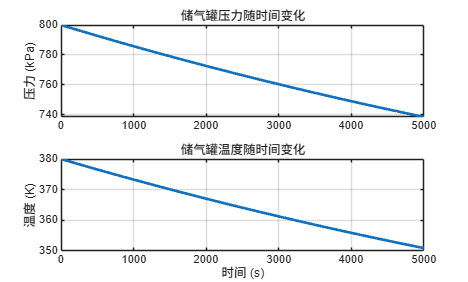

%% 储气罐参数输入（可修改）
P0 = 800;         % 初始压力 kPa
T0 = 380;         % 初始温度 K
V = 100;          % 体积 m^3
R = 0.287;        % 空气气体常数
A = 30;           % 换热面积 m^2
h = 0.00135;       % 对流换热系数
Tamb = 288;       % 环境温度 K

leak_rate = 0.00000005;   % 泄漏系数 (1/s)，越大泄漏越快
t_end = 5000;         % 仿真秒数

%% 调用模型
result = tank_leak_sim(P0, T0, V, R, A, h, Tamb, leak_rate, t_end);

%% 绘图展示
figure;
subplot(2,1,1);
plot(result.time, result.P, 'LineWidth', 2);
grid on; ylabel('压力 (kPa)'); title('储气罐压力随时间变化');

subplot(2,1,2);
plot(result.time, result.T, 'LineWidth', 2);
grid on; ylabel('温度 (K)'); xlabel('时间 (s)');
title('储气罐温度随时间变化');